rng(100,"twister");
omap2D =  occupancyMap(1000, 1000, 0.1);
mapWidth = 1000;
mapLength = 1000;
numberOfObstacles = 1;

width = 190;                 % The largest integer in the sample intervals for obtaining width, length and height                                                     
length = 20;                % can be changed as necessary to create different occupancy maps.
height = 200;

tic
posx = [200, 200, 600, 600] ;
posy = [250, 750, 250, 750;];

for j = 1:4
    xpos1 = posx(1,j);
    ypos1 = posy(1,j);
    
    [xObstacle,yObstacle] = meshgrid(xpos1:xpos1+width,ypos1:ypos1+length);
    xyObstacles = [xObstacle(:) yObstacle(:)];
    setOccupancy(omap2D,xyObstacles, 1);
end
toc

Elapsed time is 0.006673 seconds.


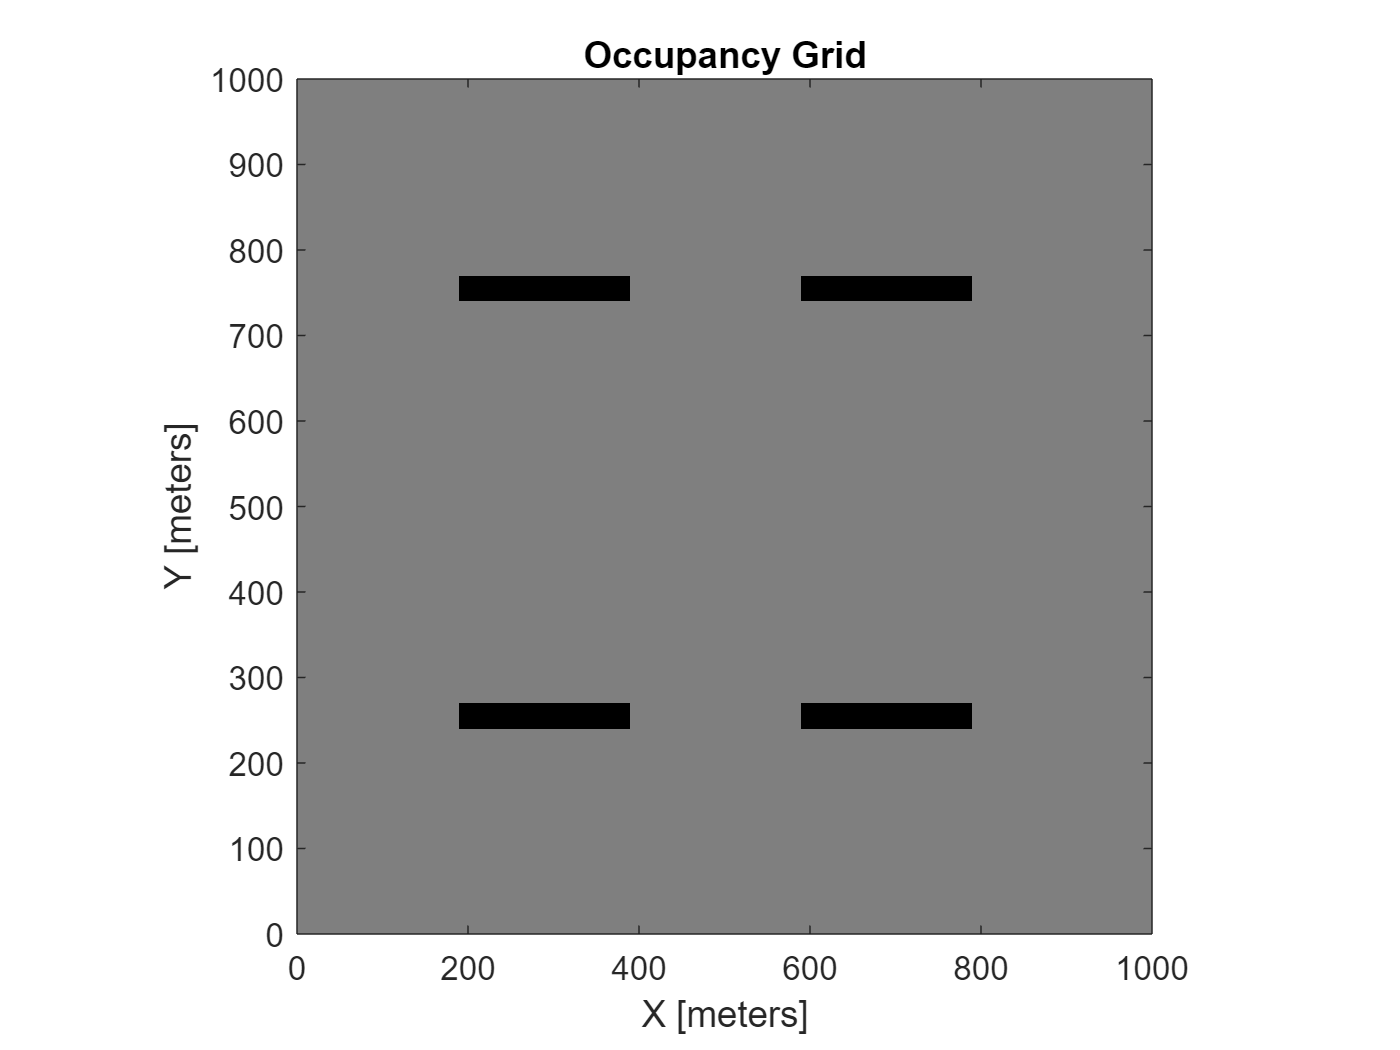


tic
figure("Name","2D Occupancy Map")
show(omap2D)

toc

Elapsed time is 0.031710 seconds.



filePath = fullfile(pwd, "testing_map2.mat" )

filePath = "C:\Users\jipva\MATLAB\Projects\drone\Detailed design phase\guidance\testing_map2.mat"

%exportmat = occupancyMatrix(omap3D)
save(filePath, "omap2D")
